# Visión Artificial: Actividad 1

## Lectura de imagen

I = imread("dataset\Image-102.png");


## Visualización 

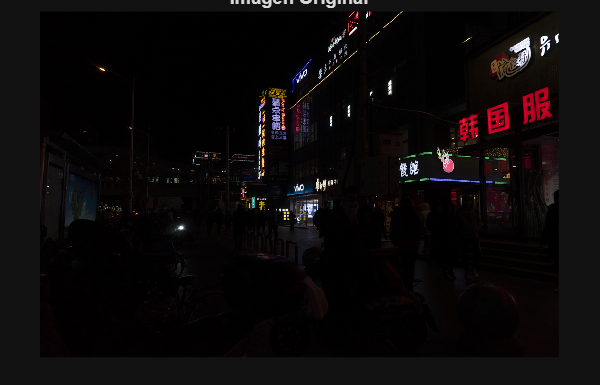

imshow(I);
title('Imagen Original');

fprintf('Rango para la imagen orginal: ')

Rango para la imagen orginal: 

## Corrección gamma

I = im2double(I);
fprintf('Rango para la imagen normalizada')

Rango para la imagen normalizada

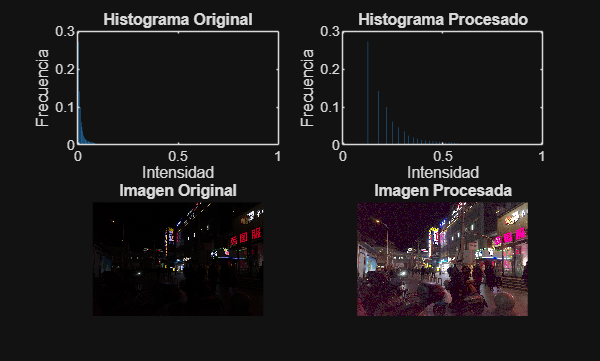

gamma = 0.5; % Gamma inferior a 1 permite aclarar la imagen
c = 2;
IGamma = IGammaFunction(I, c, gamma);
metrics = compareIntensityMetrics(I, IGamma);
visualizerFunction(I, IGamma, metrics.histograms)


% Metricas:
getMetrics(metrics)

originalSTD = 0.0980

processSTD = 0.2577

originalEntropy = 3.9393

processEntropy = 3.7713

originalUniformity = 0.9843

processUniformity = 0.9843

ssim = 0.0752

## Método Modificaciones de Intensidad

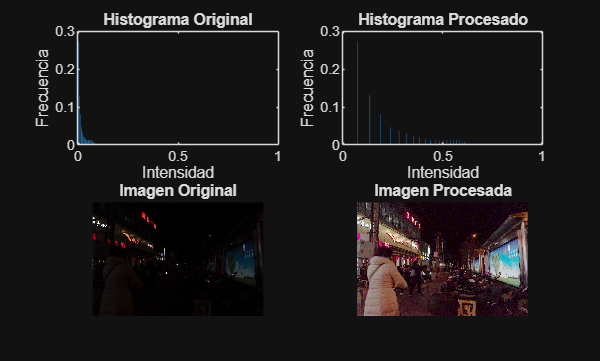

I = imread("dataset\Image-1005.png");
I = im2double(I);
a = 1;
K = 0.05;
e = 1;
IStreched = INoLinealContrast(I, a, K, e);
metrics = compareIntensityMetrics(I, IStreched);
visualizerFunction(I, IStreched, metrics.histograms)


% Metricas:
getMetrics(metrics)

originalSTD = 0.0677

processSTD = 0.2179

originalEntropy = 3.9532

processEntropy = 3.9388

originalUniformity = 0.9844

processUniformity = 0.9844

ssim = 0.0802

## Método Logaritmico

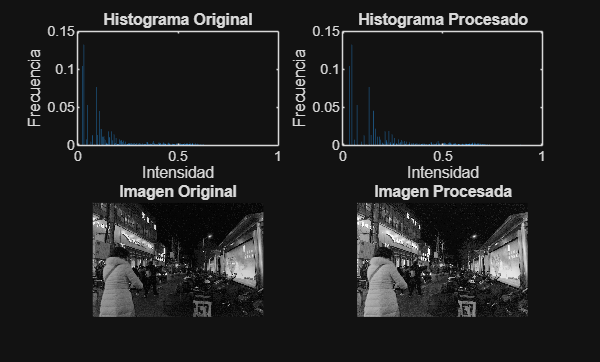

%I = rgb2gray(imread("dataset\Image-1022.png"));
I = rgb2gray(IStreched);
I = im2double(I);
c = 1.5;
ILog = ILogFunction(I,c);
metrics = compareIntensityMetrics(I, ILog);
visualizerFunction(I, ILog, metrics.histograms)


% Metricas:
getMetrics(metrics)

originalSTD = 0.2116

processSTD = 0.2420

originalEntropy = 6.4085

processEntropy = 6.4316

originalUniformity = 0.9911

processUniformity = 0.9911

ssim = 0.9355

## Ecualización de histograma

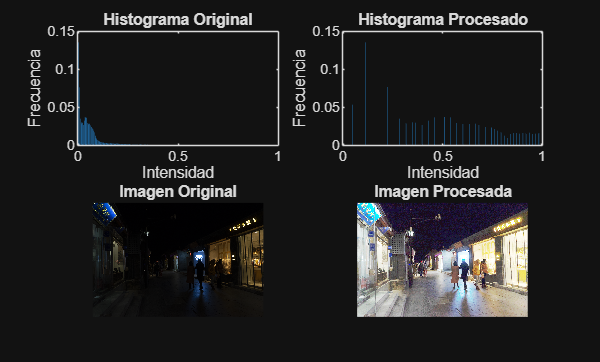

I = imread("dataset\Image-1019.png");
I = im2double(I);
I_eq = histeq(I);
metrics = compareIntensityMetrics(I, I_eq);
visualizerFunction(I, I_eq, metrics.histograms)


% Metricas:
getMetrics(metrics)

originalSTD = 0.1108

processSTD = 0.2908

originalEntropy = 5.3814

processEntropy = 4.8366

originalUniformity = 0.9910

processUniformity = 0.9907

ssim = 0.1033

## Operaciones Aritméticas

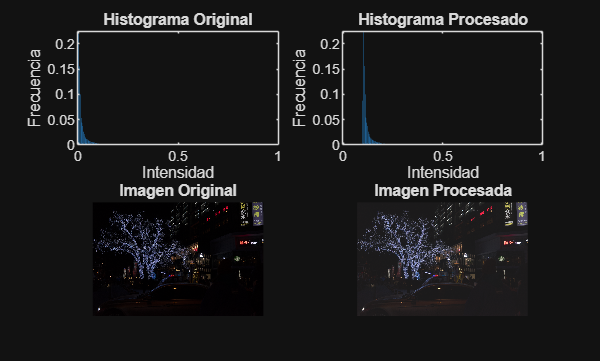

I = imread("dataset\Image-1010.png");
I = im2double(I);
cSum = 0.1;
cMult = 2.5;
% Operación  Suma
operation = operationFunction(I, cSum, cMult);
% Visualizar la imagen resultante de la operación
metrics = compareIntensityMetrics(I, operation.ISum);
visualizerFunction(I, operation.ISum, metrics.histograms);

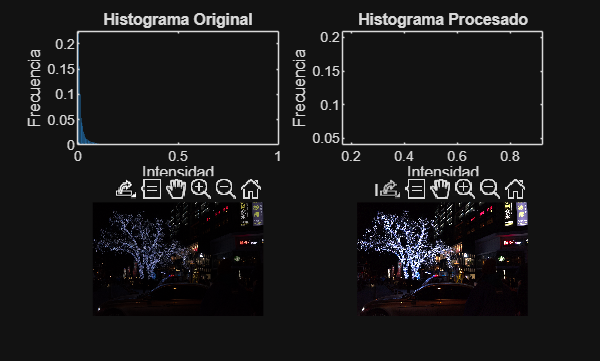


% Visualizar la imagen resultante de la operación
metrics = compareIntensityMetrics(I, operation.Imult);
visualizerFunction(I, operation.Imult, metrics.histograms);


% Metricas:
getMetrics(metrics)

originalSTD = 0.1097

processSTD = 0.2742

originalEntropy = 4.5042

processEntropy = 4.3257

originalUniformity = 0.9861

processUniformity = 0.9860

ssim = 0.6406

## Crear función para comparar intensidades

%Función para comparar intensidades entre I y IGamma
function metrics = compareIntensityMetrics(I, IProcess)
    originalRange = max(I(:)) - min(I(:));
    % Garantizar la normalización de rango de intensidad
    I = im2double(I);
    IProcess  = im2double(IProcess);

    % Número de niveles para histograma
    nBins = 512;
    calcHist = @(img) imhist(img, nBins) / numel(img);
    % Cálculo de histograma
    pI = calcHist(I);
    pIProcess = calcHist(IProcess);

    histograms = struct('originalHistogram', pI, 'processedHistogram', pIProcess);
    
    % ---- METRICAS ---- %
    % Rango dinámico
    processRange = max(IProcess(:)) - min(IProcess(:));
    
    % Desviación estándar
    originalSTD = std(I(:));
    processSTD = std(IProcess(:));

    % Entropía 
    originalEntropy = -sum(pI .* log2(pI + eps));
    processEntropy = -sum(pIProcess .* log2(pIProcess + eps));

    % Contraste Michelson
    originalMichelson = (max(I(:)) - min(I(:))) / (max(I(:)) + min(I(:)) + eps);
    processMichelson = (max(IProcess(:)) - min(IProcess(:))) / (max(IProcess(:)) + min(IProcess(:)) + eps);

    % Uniformidad de Histograma
    originalHistUniformity = 1 - std(pI);
    processHistUniformity = 1 - std(pIProcess);

    % SSIM
    ssimVal  = ssim(IProcess, I);

    % Resultados
    metrics.histograms = histograms;

    metrics.originalRange = originalRange;
    metrics.processRange = processRange;

    metrics.originalSTD = originalSTD;
    metrics.processSTD = processSTD;

    metrics.originalEntropy = originalEntropy;
    metrics.processEntropy = processEntropy;
    
    metrics.originalMichelson = originalMichelson;
    metrics.processMichelson = processMichelson;

    metrics.originalHistUniformity = originalHistUniformity;
    metrics.processHistUniformity = processHistUniformity;

    metrics.ssimVal = ssimVal;
end

## Función para visualizar imagenes

function visualizerFunction(I, IProcess, metrics)
    % Normalizar ejes:
    nBins = numel(metrics.originalHistogram);
    x = linspace(0, 1, nBins);  % Eje X normalizado


    % Visualización de histograma
    figure;
    subplot(2, 2, 1);
    bar(x, metrics.originalHistogram, 'BarWidth', 1);
    title('Histograma Original');
    xlabel('Intensidad');
    ylabel('Frecuencia');

    subplot(2, 2, 2);
    bar(x, metrics.processedHistogram, 'BarWidth', 1);
    title('Histograma Procesado');
    xlabel('Intensidad');
    ylabel('Frecuencia');

    % Visualizar la imagen procesada
    subplot(2, 2, 3);
    imshow(I);
    title('Imagen Original');

    subplot(2, 2, 4);
    imshow(IProcess);
    title('Imagen Procesada');
end


## Función Corrección Gamma

function IGamma = IGammaFunction(I, c, gamma)
    IGamma = c * (I.^ gamma);
end

## Función Estiramiento Lineal del Contraste

function ILinealContrast(I, factor)
    % Factor de atenuación
    ILow = I(:) * factor; % Consiste en multiplicar por un factor
    % Normalización lineal
    IMin = min(ILow(:));
    IMax = max(ILow(:));
    INorm = (ILow - IMin) / (IMax - Imin);
    
    % Función histograma
    nBins = 512;

    calcHist = @(img) imhist(img, nbins) / numel(img); % Histograma

    % Ejes de intensidad
    x = linspace(0, 1, nBins);
    % Calculo de histograma
    originalHistogram = calcHist(I);
    lowHistogram = calcHist(ILow);
    normHistogram = calcHist(INorm);
end


## Función Estiramiento No Lineal del Contraste

function IStreched = INoLinealContrast(I, a, K, e)
    IStreched = a ./ (1 + (K ./ I).^e);
end

## Función Transformación Logaritmica

function ILog = ILogFunction(I, c)
    ILog = c * log(1 + I);
    ILog = (ILog - min(ILog(:))) / (max(ILog(:)) - min(ILog(:))) * 1;
end

## Función Operaciones Aritméticas

function operation = operationFunction(I,cSum, cMult)
    % Operación suma
    ISum = I + cSum;
    % Operación Mult
    Imult = I * cMult;

    % Resultado
    operation.ISum = ISum;
    operation.Imult = Imult;
end

## Función Obtener metricas

function getMetrics(metrics)
    % Metricas:
    originalSTD = metrics.originalSTD
    processSTD = metrics.processSTD
    originalEntropy = metrics.originalEntropy
    processEntropy = metrics.processEntropy
    originalUniformity = metrics.originalHistUniformity
    processUniformity = metrics.processHistUniformity
    ssim = metrics.ssimVal
end